# Parameter Sweep for Reduction Gear Ratio and Battery Size

This script demonstrates a parameter sweep workflow to investigate the effect of reduction gear ratio, high-voltage battery capacity and high-voltage battery weight on the electrical efficiency. Note that this script is configured to finish soon for demonstration purpose.

## Problem Setup

### Drive Cycle & Simulation Configuration

Select drive cycle. Also select serial simulation with `sim` or parallel simulation with `parsim`. Long drive cycle such as FTP-75 can benefit from parallel simulation, but short drive cycle may not. The number of simulations is another factor to consider. To use `parsim`, Parallel Computing Toolbox is required.

Note that simulation might not be able to complete if parameter set is not properly configuring the vehicle. For example, insufficient reduction gear ratio (i.e., reduced torque performance) with large battery (i.e. heavy weight) can result in a poor performing vehicle setup which might not be able to track the refernece vehicle speed.

driveCycle = "SimpleDrivePattern";  % Short drive cycle.
% driveCycle = "FTP75";  % Simulation time is more than 2000 second.

useParsim_tf = false;  % Set true or false.

Show the Simulation Manager or not.

showSimulationManager_onoff = "off";  % 'on' or 'off'

Vehicle model

mdl = "PowerSplitHEV_system_model";

Signal name of electrical efficiency. The model must have a signal with this name.

elecEffSignalName = "Electrical Efficiency (kW/100km)";

### Grid Points in Sweep Space

Reduction gear ratios to sweep.

% GearRatio_values = [0.2, 0.23, 0.26, 0.29, 0.32, 0.35];
GearRatio_values = [0.2, 0.28, 0.35];

Capacity and weight of high-voltage battery to sweep. They must have the same number of elements.

% nominalCapacity_kWhr_values = [0.5, 1.0, 1.5, 2.0];
% batteryWeight_kg_values     = [110, 125, 140, 155];

nominalCapacity_kWhr_values = [0.5, 1.2, 2.0];
batteryWeight_kg_values     = [100, 115, 130];

assert(all(size(nominalCapacity_kWhr_values) == size(batteryWeight_kg_values)))

### Problem-Related Parameters

Cell voltage represents the type of battery chemistry.

cellVoltage_V = 3.5;  % assuming Li-ion

Initial State-of-Charge (SOC) can significantly affect the hybrid-driving mode transitions during simulation.

initialSOC_pct = 85;

The sum of the following weights and the high-voltage battery weight is the total system weight, which is computed in the Derived Parameters section.

vehicleWeight_kg = 1300;  % Vehicle body, coolant, and oil.
engineFuelWeight_kg = 50*0.75;  % (volume) * (specific gravity)
loadWeight_kg = 70*2;  % Passengers and other goods.

Parameters below are used for the HEV controller and related to this workflow.

% SOC value between "mid" and "high" in the HEV controller.
% The controller stops charging high-voltage battery
% if SOC is above this threshold.
highVoltageBatterySoc_HighMidThreshold_pct = 90;

% The HEV controller starts charging high-voltage battery
% if 1) vehicle speed is above this threshold
% and 2) battery charge level is mid or low.
vehicleSpeedThresholdForCharging_kph = 100;

## Derived Parameters

Number of parameter sets

numReductionGearRatioVariations = numel(GearRatio_values)

numReductionGearRatioVariations = 3

numBatterySizeVariations= numel(nominalCapacity_kWhr_values)

numBatterySizeVariations = 3

numParamSets = numBatterySizeVariations*numReductionGearRatioVariations;
disp("Number of parameter sets: " + numParamSets)

Number of parameter sets: 9


Amp-hour rating, i.e., charge, determined from capacity and cell voltage.

nominalCharge_Ahr_values = nominalCapacity_kWhr_values.*1000/cellVoltage_V

nominalCharge_Ahr_values =   142.8571  342.8571  571.4286


Total system weight

systemWeight_kg_values = ...
  vehicleWeight_kg + engineFuelWeight_kg + loadWeight_kg + batteryWeight_kg_values

systemWeight_kg_values = 1.0e+03 *

    1.5775    1.5925    1.6075


## Build Parameter Sets to Explore

params = struct( ...
  'ID',[], ...
  'gearRatio',[], ...
  'nominalCapacity_kWhr',[], ...
  'nominalCharge_Ahr',[], ...
  'batteryWeight_kg',[], ...
  'systemWeight_kg',[], ...
  'initialCharge_Ahr',[] );

[nominalCapacity_kWhr_grid, ~] = meshgrid(nominalCapacity_kWhr_values, GearRatio_values);
[nominalCharge_Ahr_grid, ~] = meshgrid(nominalCharge_Ahr_values, GearRatio_values);
[batteryWeight_kg_grid, ~] = meshgrid(batteryWeight_kg_values, GearRatio_values);
[systemWeight_kg_grid, GearRatio_grid] = meshgrid(systemWeight_kg_values, GearRatio_values);

for paramIdx = 1:numParamSets
  params(paramIdx).ID = "P" + paramIdx;
  params(paramIdx).gearRatio = GearRatio_grid(paramIdx);

  params(paramIdx).nominalCapacity_kWhr = nominalCapacity_kWhr_grid(paramIdx);
  params(paramIdx).nominalCharge_Ahr = nominalCharge_Ahr_grid(paramIdx);
  params(paramIdx).batteryWeight_kg = batteryWeight_kg_grid(paramIdx);
  params(paramIdx).systemWeight_kg = systemWeight_kg_grid(paramIdx);

  params(paramIdx).initialCharge_Ahr = ...
    params(paramIdx).nominalCharge_Ahr * initialSOC_pct/100;
end

Visualize the defined parameter sets. The row names P1, P2, etc. mean Parameter set 1, Parameter set 2, etc.

paramTbl = struct2table(params);
paramTbl.Properties.RowNames = paramTbl.ID;
paramTbl.ID = [];
disp(paramTbl)

          gearRatio    nominalCapacity_kWhr    nominalCharge_Ahr    batteryWeight_kg    systemWeight_kg    initialCharge_Ahr
          _________    ____________________    _________________    ________________    _______________    _________________

    P1       0.2               0.5                  142.86                100               1577.5              121.43      
    P2      0.28               0.5                  142.86                100               1577.5              121.43      
    P3      0.35               0.5                  142.86                100               1577.5              121.43      
    P4       0.2               1.2                  342.86                115               1592.5    

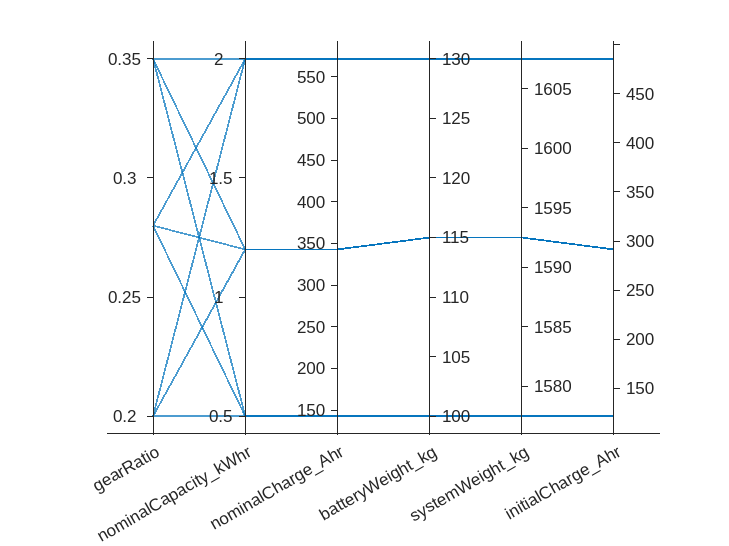

figure
parallelplot(paramTbl, Jitter=0);

## Simulation Setup

To run multiple simulations efficiently, Fast Restart is used. Fast Restart requires Simscape block parameters to be run-time configurable. For more information on these topics, see the following pages.

- [https://www.mathworks.com/help/simulink/ug/fast-restart-workflow.html](https://www.mathworks.com/help/simulink/ug/fast-restart-workflow.html)

- [https://www.mathworks.com/help/physmod/simscape/ug/about-simscape-run-time-parameters.html](https://www.mathworks.com/help/physmod/simscape/ug/about-simscape-run-time-parameters.html)

### Open model

% Default settings loaded here will be overridden later.
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

% Use the speed tracking controller.
set_param(mdl+"/Controller & Environment", ...
  ReferencedSubsystem = "PowerSplitHEV_SpeedTracking_refsub");

simMode = get_param(mdl, "SimulationMode");
assert(simMode == "normal")

solverName = get_param(mdl, "SolverName");
assert(solverName == "daessc")

### Load Variables in Base Workspace

External input - vehicle speed reference

inputPattern = driveCycle;
disp(inputPattern)

SimpleDrivePattern


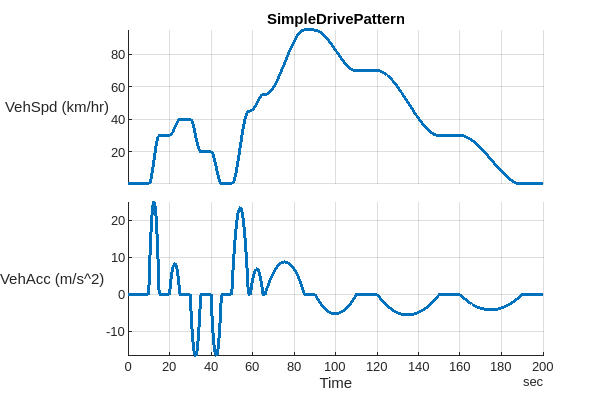

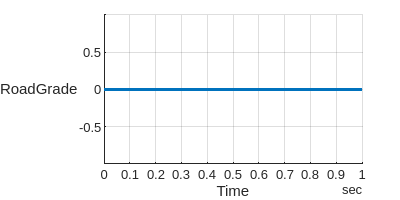

% This function loads some variables in the base workspace.
PowerSplitHEV_SpeedTracking_selectInput( ...
  InputPattern = inputPattern, ...
  DisplayPlot = true );

Simulation time

t_end

t_end = 200

Load default parameters. Some of these are overridden by Simulation Input objects.

PowerSplitHEV_params

### Build Simulation Input Objects

%simIn(1:numParamSets) = Simulink.SimulationInput(mdl);  % error in R2022a.
simIn(1:numParamSets) = Simulink.SimulationInput(char(mdl));
for paramIdx = 1 : numParamSets
  simIn(paramIdx) = setModelParameter(simIn(paramIdx), ...
    StopTime = num2str(t_end));

  % Controller

  simIn(paramIdx) = setVariable(simIn(paramIdx), ...
    "hevcontrol.hvbattSocHighMid_pct", ...
    highVoltageBatterySoc_HighMidThreshold_pct);

  simIn(paramIdx) = setVariable(simIn(paramIdx), ...
    "hevcontrol.chgSpd_kph", ...
    vehicleSpeedThresholdForCharging_kph);

  simIn(paramIdx) = setVariable(simIn(paramIdx), ...
    "hevcontrol.hvbattNominalCapacity_Ahr", ...
    params(paramIdx).nominalCharge_Ahr);

  simIn(paramIdx) = setVariable(simIn(paramIdx), ...
    "initial.controllerHVBattSOC_pct", initialSOC_pct);

  % Plant

  simIn(paramIdx) = setVariable(simIn(paramIdx), ...
    "powerSplit.reducer_differentialGearRatio", ...
    params(paramIdx).gearRatio);

  simIn(paramIdx) = setVariable(simIn(paramIdx), ...
    "vehicle.mass_kg", params(paramIdx).systemWeight_kg);

  simIn(paramIdx) = setVariable(simIn(paramIdx), ...
    "initial.hvBatteryCapacity_Ahr", ...
    params(paramIdx).initialCharge_Ahr);
end

## Run Simulations

Note that total simulation time strongly depends not only on serial or parallel simulation but also on the drive cycle and computer power. For example, in a typical desktop PC with 6 cores, parsim for FTP-75 drive cycle can take 4 minutes or more.

switch useParsim_tf
case true
  tic
  simOut = parsim(simIn, ShowSimulationManager=showSimulationManager_onoff, ...
              UseFastRestart="on");
  toc
otherwise
  tic
  simOut = sim(simIn, ShowSimulationManager=showSimulationManager_onoff, ...
              UseFastRestart="on");
  toc
end

[12-Jan-2023 19:27:22] Running simulations...
[12-Jan-2023 19:28:16] Completed 1 of 9 simulation runs
[12-Jan-2023 19:28:42] Completed 2 of 9 simulation runs
[12-Jan-2023 19:29:23] Completed 3 of 9 simulation runs
[12-Jan-2023 19:29:47] Completed 4 of 9 simulation runs
[12-Jan-2023 19:30:10] Completed 5 of 9 simulation runs
[12-Jan-2023 19:30:52] Completed 6 of 9 simulation runs
[12-Jan-2023 19:31:15] Completed 7 of 9 simulation runs
[12-Jan-2023 19:31:37] Completed 8 of 9 simulation runs
[12-Jan-2023 19:32:17] Completed 9 of 9 simulation runs


Elapsed time is 296.380675 seconds.


## Process and Visualize Results

Collect simulation results.

result_struct = struct( ...
  'ID',[], ...
  'ElapsedTime',[], ...
  'SpeedUp',[], ...
  'ElectricalEfficiency_kWper100km',[]);

for paramIdx = 1 : numParamSets
  result_struct(paramIdx).ID = "P" + paramIdx;

  t_elapsed = simOut(paramIdx).SimulationMetadata.TimingInfo.TotalElapsedWallTime;
  result_struct(paramIdx).ElapsedTime = t_elapsed;
  result_struct(paramIdx).SpeedUp = t_end / t_elapsed;

  tmp_sig = simOut(paramIdx).logsout.get(elecEffSignalName).Values;  % *.Time, *.Data
  result_struct(paramIdx).ElectricalEfficiency_kWper100km = mean(tmp_sig.Data);
end

View the results in table.

resultTbl = struct2table(result_struct);
resultTbl.Properties.RowNames = resultTbl.ID;
resultTbl.ID = [];
disp(resultTbl)

          ElapsedTime    SpeedUp    ElectricalEfficiency_kWper100km
          ___________    _______    _______________________________

    P1      53.386       3.7463                 182.42             
    P2      25.792       7.7543                 189.14             
    P3      40.964       4.8823                 82.775             
    P4      23.574       8.4838                 189.25             
    P5      23.197       8.6218                 193.95             
    P6      42.013       4.7604                 81.318             
    P7      22.151       9.0289                 192.54             
    P8      22.701       8.8103                 193.28             
    P9      39.907       5.0116                 79.975          

Average speed up of all simulation runs

mean(resultTbl.SpeedUp)

ans = 6.7889

Build a table containing the parameters sets and the corresponding results.

sweepTbl = paramTbl(:, ["gearRatio", "nominalCapacity_kWhr", "batteryWeight_kg"]);
elecEffTbl = resultTbl(:, "ElectricalEfficiency_kWper100km");
combinedTbl = join(sweepTbl, elecEffTbl, Keys="Row");

Sort the results based on the efficiency.

[sortedCombinedTbl, sortedIdx] = sortrows(combinedTbl, "ElectricalEfficiency_kWper100km", "ascend");
disp(head(sortedCombinedTbl, min(numParamSets,5)))

          gearRatio    nominalCapacity_kWhr    batteryWeight_kg    ElectricalEfficiency_kWper100km
          _________    ____________________    ________________    _______________________________

    P9      0.35                 2                   130                       79.975             
    P6      0.35               1.2                   115                       81.318             
    P3      0.35               0.5                   100                       82.775             
    P1       0.2               0.5                   100                       182.42             
    P2      0.28               0.5                   100                       189.14             



clear Ranking
Ranking(1:numParamSets, 1) = "Other";
Ranking(1) = "Best";
if numParamSets >= 2, Ranking(2) = "2nd Best"; end
% if numParamSets >= 3, Ranking(3) = "3rd Best"; end
rankingTbl = table(Ranking, 'RowNames', "P" + sortedIdx);
disp(head(rankingTbl, min(numParamSets,5)))

           Ranking  
          __________

    P9    "Best"    
    P6    "2nd Best"
    P3    "Other"   
    P1    "Other"   
    P2    "Other"   



Show the final results.

rankedCombinedTbl = join(sortedCombinedTbl, rankingTbl, "Keys","Row");
disp(rankedCombinedTbl)

          gearRatio    nominalCapacity_kWhr    batteryWeight_kg    ElectricalEfficiency_kWper100km     Ranking  
          _________    ____________________    ________________    _______________________________    __________

    P9      0.35                 2                   130                       79.975                 "Best"    
    P6      0.35               1.2                   115                       81.318                 "2nd Best"
    P3      0.35               0.5                   100                       82.775                 "Other"   
    P1       0.2               0.5                   100                       182.42                 "Other"   
    P2      0.28               0.5                   100          

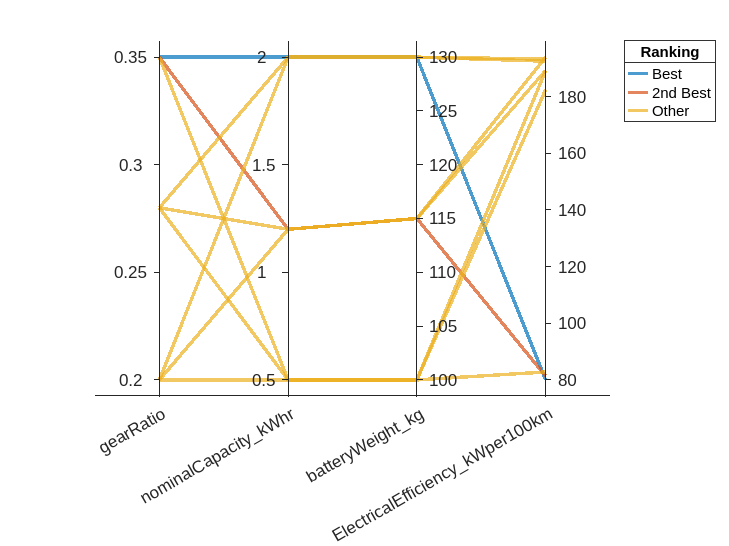

figure
parallelplot(rankedCombinedTbl, ...
  CoordinateVariables = ["gearRatio", "nominalCapacity_kWhr",...
    "batteryWeight_kg", "ElectricalEfficiency_kWper100km"],...
  GroupVariable = "Ranking", ...
  Jitter=0, LineWidth=2)

*Copyright 2021-2022 The MathWorks, Inc.*